close all
clear
clc

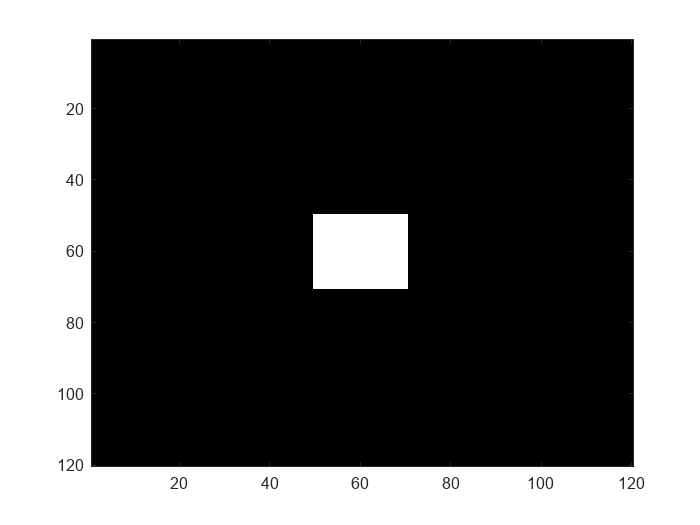

A = zeros(120, 120, 3);
A(size(A)/2-10:size(A)/2+10, size(A)/2-10:size(A)/2+10, :) = 10;
imagesc(A);

x = 60; 
y = 60; 
z = 2;

Blocco per settare i valori iniziali dell'evoluzione.


N_start = 27;  % Numero iniziale di formiche, non può eccedere 27
Ant(1:N_start) = ant;
init_voxel = [x, y, z];
voxel_count = [];  % Matrice le cui righe sono le coordinate di ogni voxel visitato
coordinates = initialize_coordinates(A, N_start, x, y, z);
pheromone_map = initialize_pheromone_map(A);
pheromone = [];  % Quantità di feromone rilasciato per ciclo al netto di ant.eta
delta_pheromone = [];  % Media di feromone rilasciato per ogni ciclo al netto di ant.eta
cell_num_cycle = {N_start; 0};  % Cella che conserva il numero di formiche ed il numero del ciclo
N_threshold = 40;  % Numero massimo di visite in un voxel e per cui questo è considerato come segmentato
e_death = 1;
e_reproduction = 1.3;

Inizializza le coordinate delle formiche.

for i=1:N_start
    Ant(i).x = coordinates(i, 1);
    Ant(i).y = coordinates(i, 2);
    Ant(i).z = coordinates(i, 3);
end

tic
cycles = 1;
N = N_start;
size_ants = 0;
while cycles < 1000
    j = 1;


Ciclo sul numero di formiche per marcare i voxel, rilasciare il feromone e salvare le coordinate dei voxel visitati.

    while j <= length(Ant)
        pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 2) = Ant(j).mark_voxel();
        pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 1) = pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 1) + Ant(j).pheromone_release(A);        
        voxel_count = [voxel_count; [Ant(j).x, Ant(j).y, Ant(j).z]];
        pheromone = [pheromone, Ant(j).pheromone_release(A) - Ant(j).eta];
        j = j + 1;
    end

    delta_pheromone = [delta_pheromone, sum(pheromone)/numel(pheromone)];
    j = 1;


Ciclo sul numero di formiche per valutarne ed aggiornarne l'energia. Se l'energia di una formica è minore di e_death, questa lascerà il voxel e verrà eliminata dall'array di formiche. Se l'energia è maggiore di e_reproduction allora l'energia della formica verrà resettata al valore iniziale e verrà posta una formica figlia in uno dei voxel primi vicini liberi e con un valore di fermone minore della soglia prestabilita; nel caso in cui non ci siano voxel disponibili la formica figlia viene eliminata, altrimenti questa viene posta nel voxel scelto, lo marca e vi deposita feromone. Se il numero di formiche è minore di 1 (ovvero 0) tutti i cicli while vengono terminati.

    while j <= length(Ant)
    Ant(j).energy = Ant(j).update_energy(pheromone(j + size_ants), sum(pheromone)/numel(pheromone));
        if Ant(j).energy < e_death
            pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 2) = Ant.leave_voxel(); 
            Ant(j) = [];
            N = N - 1;
            if N<1
                break;
            end
            continue
        elseif Ant(j).energy > e_reproduction
            Ant(j).energy = 1.2;
            Daughter_ant = ant;
            Daughter_ant.x = Ant(j).x;
            Daughter_ant.y = Ant(j).y;
            Daughter_ant.z = Ant(j).z;
            next_voxel = Daughter_ant.evaluate_destination(pheromone_map, A, N_threshold);
            if isempty(next_voxel)==1
                Daughter_ant = [];
            else
                Daughter_ant.x = next_voxel(1);
                Daughter_ant.y = next_voxel(2);
                Daughter_ant.z = next_voxel(3);
                pheromone_map(Daughter_ant.x, Daughter_ant.y, Daughter_ant.z, 2) = Daughter_ant.mark_voxel();
                pheromone_map(Daughter_ant.x, Daughter_ant.y, Daughter_ant.z, 1) = pheromone_map(Daughter_ant.x, Daughter_ant.y, Daughter_ant.z, 1) + Daughter_ant.pheromone_release(A);
                Ant = [Ant, Daughter_ant];
                N = N + 1;
            end
        end
        j = j + 1;
    end

    if N < 1
        disp('Nessuna formica rimasta')
        break;
    end

    j = 1;


Ciclo sul numero di formiche per valutare il prossimo voxel di destinazione. Se non ci sono voxel liberi allora la formica lascia il voxel presente e viene eliminata dall'array, altrimenti viene lasciato il voxel presente e vengono aggiornate le coordinate con quelle del prossimo. Se il numero di formiche è minore di 1 vengono terminati tutti i cicli while.

    while j <= length(Ant)
        next_voxel = Ant(j).evaluate_destination(pheromone_map, A, N_threshold);
        if isempty(next_voxel) == 1
            pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 2) = Ant.leave_voxel();            
            Ant(j) = [];
            N = N - 1;
            if N<1
                break;
            end
            continue
        else
            pheromone_map(Ant(j).x, Ant(j).y, Ant(j).z, 2) = Ant.leave_voxel();
            Ant(j).x = next_voxel(1);
            Ant(j).y = next_voxel(2);
            Ant(j).z = next_voxel(3);
        end        
        j = j + 1;        
    end

    if N < 1
        disp('Nessuna formica rimasta_1')
        break;
    elseif N > 8000
        disp('Troppe formiche')
        break;
    end

    size_ants = size_ants + length(Ant);
    cycles = cycles + 1;
    cell_num_cycle{1} = [cell_num_cycle{1}, N];
    cell_num_cycle{2} = [cell_num_cycle{2}, cycles];
    
end

Nessuna formica rimasta


   

toc

Elapsed time is 95.074444 seconds.


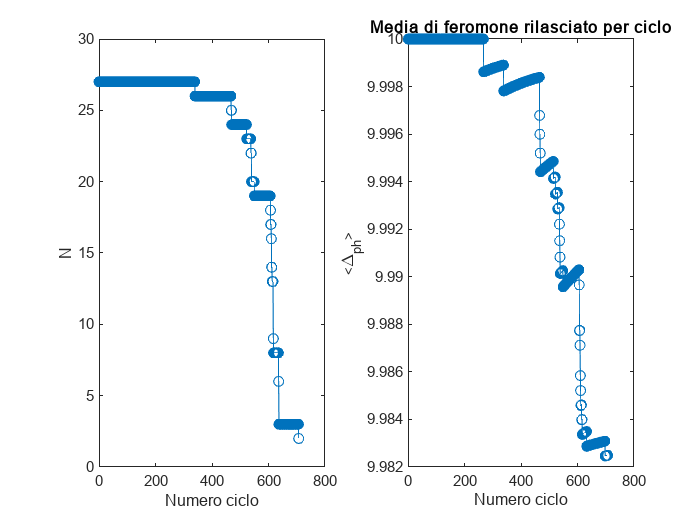

subplot(1, 2, 1);
title('Numero di formiche per ciclo')
plot(cell_num_cycle{2, :}, cell_num_cycle{1, :}, marker = 'o', linestyle = '-');
xlabel('Numero ciclo');
ylabel('N');
subplot(1, 2, 2);
if cycles>length(delta_pheromone)
    plot(1:cycles-1, delta_pheromone, marker = 'o', linestyle = '-');
else
    plot(1:cycles, delta_pheromone, marker = 'o', linestyle = '-');
end
title('Media di feromone rilasciato per ciclo')
xlabel('Numero ciclo');
ylabel('<\Delta_{ph}>')

[unique_visited_voxels,ia,ic] = unique(voxel_count, 'rows', 'stable');
h = accumarray(ic, 1);                              % Count Occurrences
visits_per_voxel = h(ic);                                       % Map Occurrences To iics Values
voxel_visits = [voxel_count, visits_per_voxel];
voxel_visits = unique(voxel_visits, 'rows', 'stable');
clear unique_visited_voxels
clear ia
clear ic
clear h
clear voxel_count

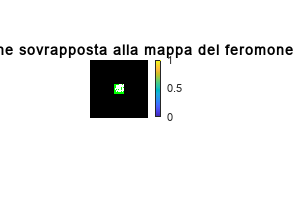

close all
PM = pheromone_map(:, :, :, 1);
imshowpair(A,PM);
colorbar;
title('Immagine sovrapposta alla mappa del feromone')

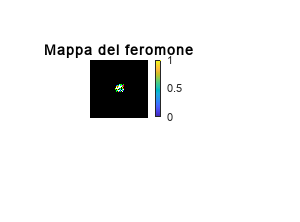


imshow(PM); 
colorbar;
title('Mappa del feromone')

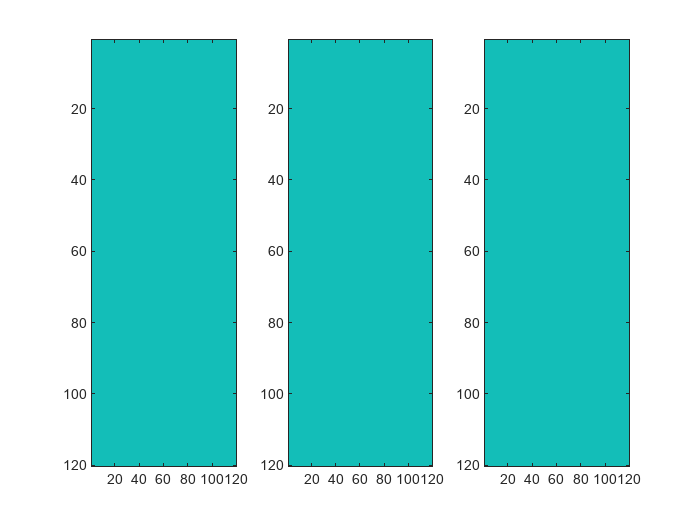

%orthosliceViewer(PM);
close all
subplot(1, 3, 1);
imagesc(pheromone_map(:, :, 1, 2));
subplot(1, 3, 2);
imagesc(pheromone_map(:, :, 2, 2));
subplot(1, 3, 3);
imagesc(pheromone_map(:, :, 3, 2));

Metriche di valutazione

N_o = nnz(A);  % Numero di voxel dell'immagine
N_v = size(voxel_visits, 1);  % Numero di voxel visitati
exploration_level = N_v/N_o

exploration_level = 0.3485

[r, s, t] = findND(PM >= (0.01 + (A - min(A(:))).*N_threshold));  % Indici dei voxel segmentati (hanno raggiunto la threshold in feromone)
segmented_voxels = [r'; s'; t'];  % Matrice le cui colonne sono le coordinate dei voxel segmentati
N_r = size(segmented_voxels, 2);  % Numero di voxel segmentati
sensitivity = N_r/N_o

sensitivity = 0.2751

contamination = exploration_level - sensitivity

contamination = 0.0733

clear r
clear s
clear t